On va essayer d'ouvrir les données afin de les visualiser et de les traiter

Définition du chemin vers les données

path = 'Unziped/A5_20190604/fichier1';
extension = 'npy';
folderlist = dir([path,'/*',extension]);

les électrodes 

FZ=2,

C3=13,

CZ=15,

C4=17,

PZ=34,

PO7=,

PO8=,

POZ=39

équivalent en numéro d'électrode

% Déclaration d'une structure pour stocker les variables
data = struct();

% Boucle pour traiter chaque fichier
for ifile = 1:length(folderlist)
    % Affichage du nom de fichier sans l'extension
    filename = folderlist(ifile).name(1:(length(folderlist(ifile).name)-4));
    disp(filename);
    
    % Lecture des données du fichier
    filepath = fullfile(path, folderlist(ifile).name);
    data.(filename) = readNPY(filepath);
end

MarkOnSignal
SampleRate
firstsignal
mark
signal
timestamp


Maintenant qu'on a stocké les données dans une structure on peut les afficher pour voir leur format

data.firstsignal;
data.mark;
data.MarkOnSignal;
data.SampleRate;
data.signal;
data.timestamp;

Data visualisées

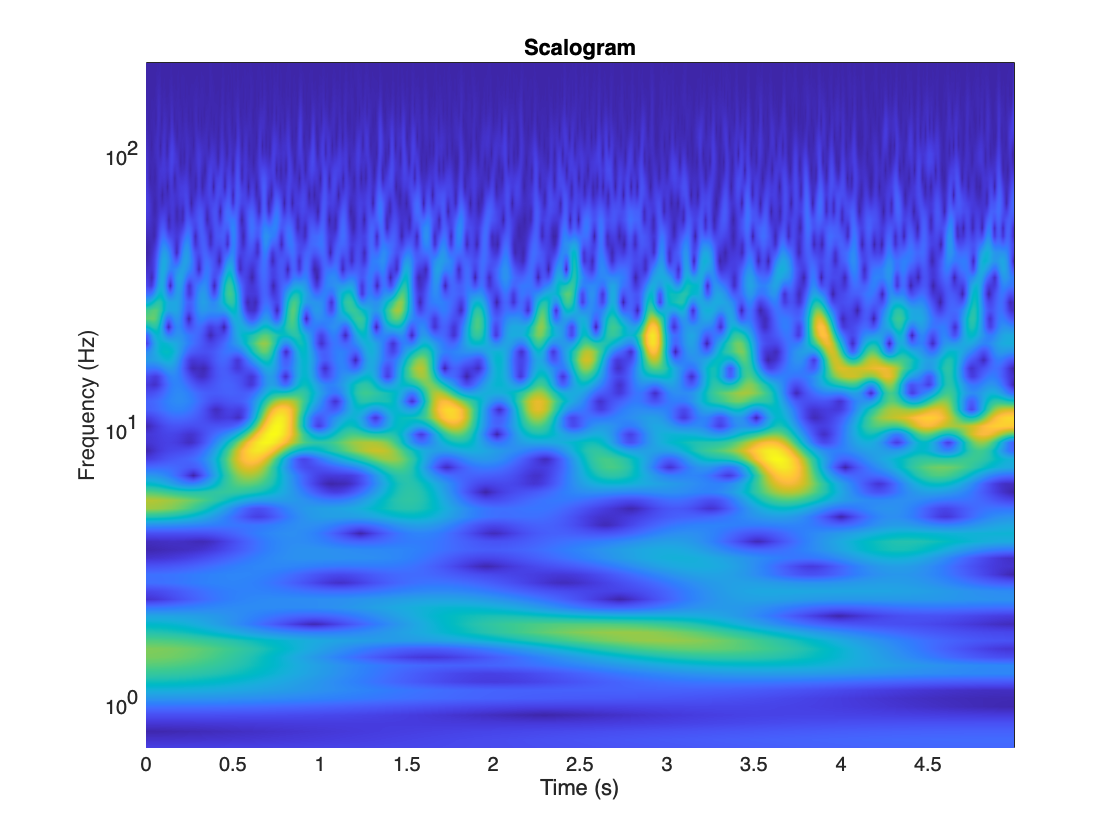

Fs = 500;
fb = cwtfilterbank(signallength=double(25600-23100),...
    samplingfrequency=Fs, ...
    wavelet="Morse");
sig = data.signal(23100:25600-1);
[cfs,frq] = wt(fb,sig);
t = (0:(25600-23100)-1)/Fs;
figure;
pcolor(t,frq,abs(cfs));
set(gca,'yscale','log');shading interp;axis tight;
title('Scalogram');xlabel('Time (s)');ylabel('Frequency (Hz)');

On va maintenant faire une boucle qui parcours les données de MarkOnSignal qui correspondent aux mouvements (main droite, main gauche, pied, croix)

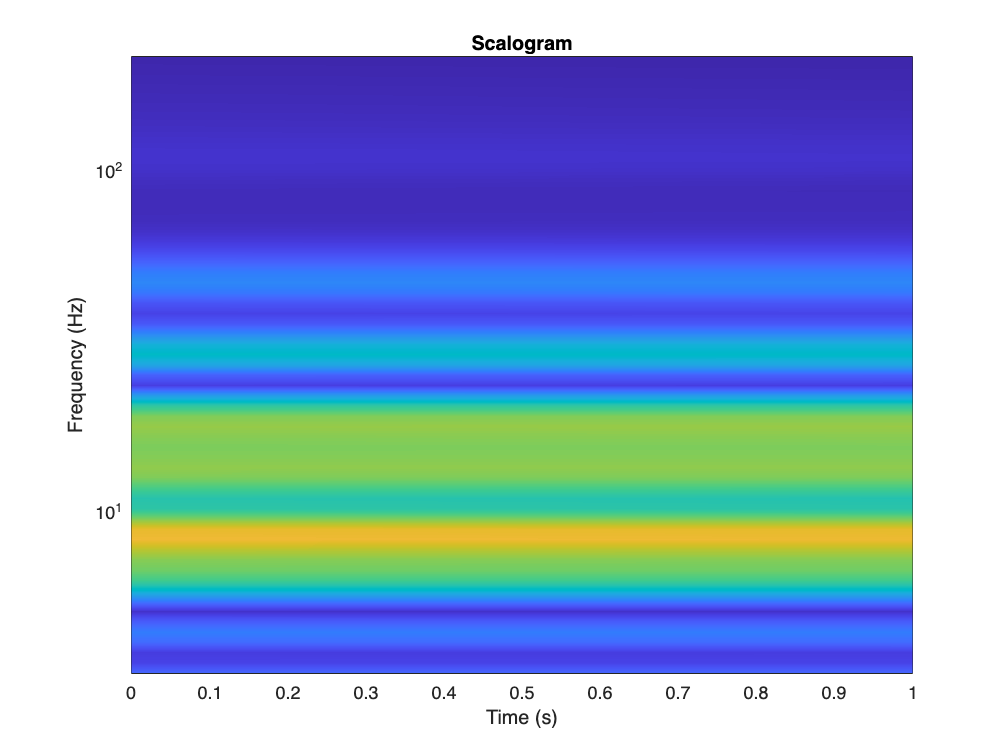

Error using saveas
Invalid or missing path: images/croix/4

Error in scalo (line 13)
    saveas(h,strcat('images/',label,'/',string(imark)),'jpg')

mark = data.MarkOnSignal;

for imark = 4:(length(mark)-1)
    indice = data.MarkOnSignal(imark);
    indice_1 = data.MarkOnSignal(imark+1);
    if data.MarkOnSignal(imark,2) == 769
        label = 'gauche';
    elseif data.MarkOnSignal(imark,2) == 770
        label = 'droite';
    elseif data.MarkOnSignal(imark,2) == 771
        label = 'pied';
    elseif data.MarkOnSignal(imark,2) == 786
        label = 'croix';
    else
        break
    end
    scalo(data.signal,indice,indice_1,label,imark);
end

signal = strcat(path2,folderlist2(ifile).name,'/','signal.npy');
mark = strcat(path2,folderlist2(ifile).name,'/','MarkOnSignal.npy');
scalo2(signal,mark);

path2 = 'Unziped/';
folderlist2 = dir(path2);
folderlist2 = folderlist2(3:length(folderlist2));
for ifolder = 1:length(folderlist2)
    filelist = dir([path2,folderlist2(ifolder).name]);
    filelist = filelist(3:length(filelist));
    for ifile = 1:length(filelist)
        psignal = fullfile(filelist(ifolder).folder,filelist(ifile).name,'signal.npy');
        pmark = fullfile(filelist(ifolder).folder,filelist(ifile).name,'MarkOnSignal.npy');
        signal = readNPY(psignal);
        mark = readNPY(pmark);
        scalo2(signal,mark,ifolder,ifile);
    end
end

on y est la


on y est la


on y est la


on y est la
